# Polynomial Regression: Bias and Variance

We demonstrate how the computed polynomial model depends on the data sample. We generate several synthetic data samples and compute and plot the polynomial model for each sample. We will see that for low degree polynomials, the models have high bias and relatively low variance. For high degree polynomials, the models have low bias and high variance.

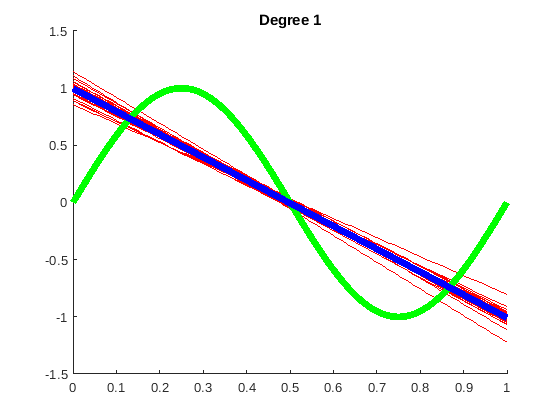

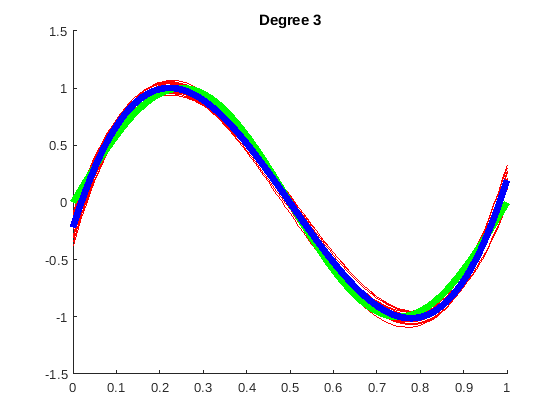

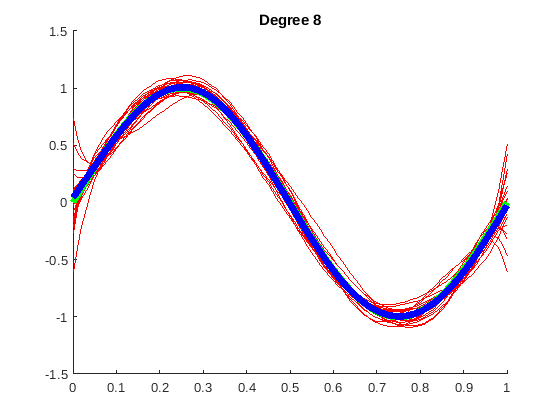

fun = @(x) sin(2*pi*x); % true function
sigma2 = 0.1;           % noise variance
ns = 20;                % number of samples
n = 200;                % number of observations in each sample

% pick a polynomial degree
for deg = [1 3 8]
  
  % set up the figure
  figure(deg)
  clf
  axis([0 1 -1.5 1.5]);
  title(sprintf('Degree %d', deg))
  hold on

  % use the same samples for each polynomial degree
  rng(0);

  % keep track of the average model
  average_model = zeros(size((0:.01:1)'));

  % loop the samples
  for s = 1:ns
    % generate the sample
    x = rand(n,1);
    y = fun(x) + sqrt(sigma2)*randn(size(x));
  
    % Set up the least squares design matrix for polynomials up to degree 9.
    X0 = [ones(n,1) x x.^2 x.^3 x.^4 x.^5 x.^6 x.^7 x.^8 x.^9];
  
    % compute the polynomial weights
    X = X0(:,1:deg+1);
    w = X\y;
  
    % compute the polynomial at values of xx
    xx = (0:.01:1)';
    yy = w(1)*ones(size(xx));
    for k = 1:deg
      yy = yy + w(k+1)*(xx.^k);
    end

    average_model = average_model + yy;
  
    % plot the polynomial
    plot(xx,yy,'r-');
  end

  % plot the true function
  fplot(fun, [0 1], 'g-', 'linewidth', 5);

  % plot the average model
  plot(xx, average_model/ns,'b-', 'linewidth', 5);
end

The true function is plotted in green. Each model computed from a sample is plotted in red. The average model is plotted in blue. For degree 1, the bias of the model is high, and it decreases as the polynomial degree is increased (we can see less of the true green curve behind the average model blue curve). As the degree is increased from 3 to 8, the variance is also obviously increased, since we see the red curves are more dispersed around the average curve.

### Taking it further

The next step is to calculate the square of the bias and the variance for these examples. Try it out!